GRE_st.name='GRE';
GRE_st.lat=34.0667;
GRE_st.lon=-109.44;
GRE_st.alt=2513;


GRE_rd=read_betsy('greer_head',GRE_st.name);

datevec(GRE_rd.Time(1))

ans =         2001           4           2           0           0           0

datevec(GRE_rd.Time(end))

ans =         2010           7           1           0           0           0

prctile(GRE_rd.U_S,[5 50 95])

ans =    16.1685   44.7425   85.8480

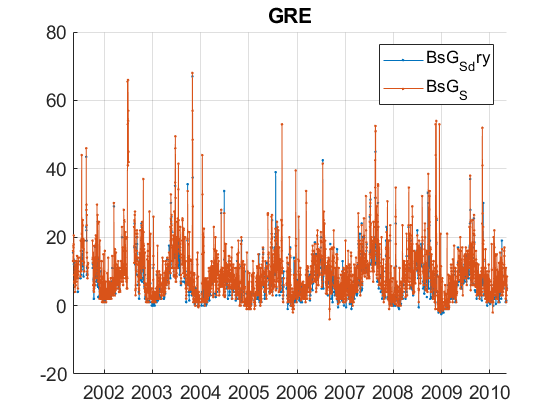

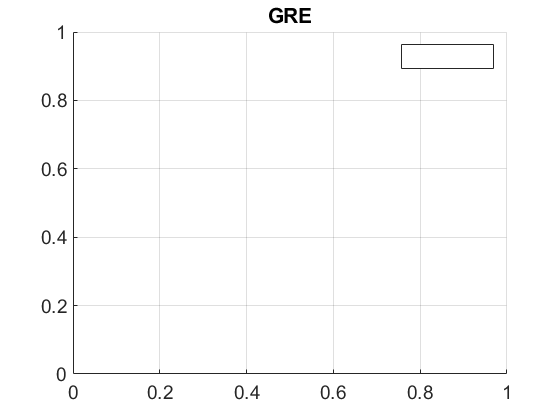

plotFigControl(GRE_rd,GRE_st.name);

% 1 size cut, ok
% sc: ok, max in summer, few negatives



% lambdaSC=[450;550;700]*ones(1,4);
% lambdaAE=[467;530;660]*ones(1,4);
% lambdaAE7=[370 470 520 590 660 880 950];
% GRE_cal=compute_exp_SSA(GRE_rd,lambdaSC, lambdaAE);
% plotFigControl_cal(GRE_cal,GRE_st.name);

%Questions:
%problems:
%sca: sca minima increases from 2012 to August 2015 and abruptly decreases thereafter: was there an intrumental change/reparation?


GRE_t=timetable(GRE_rd.Time);
% begin at the beginning of a year: 2002
%end  2009 --> too short